# ECSE403: Lab6

Jiahua Liang (260711529)

Frederic Cyr (260674545)

Xijun Liu (260654285)


% Question 1

%constants given in lab3
Kg=3.7;
rg=0.0064;
mc=0.526;
kth=0.00153;
mp=0.106;
%constants given in lab1
Jm=0.01;
Ke=0.02;
Kt=0.02;
%new constants
Km = 0.0077;
Rm = 2.6;
g =9.81;
alpha = (Kg*Km)/(rg*Rm);
beta= (alpha^2)*Rm;
lp = 0.336;

A = [0,1,0,0;
    0,(-beta)/(mc),(-mp*g)/mc,0;
    0,0,0,1;
    0,(beta)/(mc*lp),g/(lp),0]

A =          0    1.0000         0         0
         0  -14.4899   -1.9769         0
         0         0         0    1.0000
         0   43.1247   29.1964         0


B = [0;alpha/(mc);0;-alpha/(mc*lp)]

B =          0
    3.2550
         0
   -9.6876


C = eye(4)

C =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


D=[0;0;0;0]

D =      0
     0
     0
     0


%Question2
G = ss(A,B,C,D)


G =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2       0  -14.49  -1.977       0
   x3       0       0       0       1
   x4       0   43.12    29.2       0
 
  B = 
           u1
   x1       0
   x2   3.255
   x3       0
   x4  -9.688
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
 
Continuous-time state-space model.



tf(G)


ans =
 
  From input to output...
                3.255 s^2 - 75.88
   1:  ------------------------------------
       s^4 + 14.49 s^3 - 29.2 s^2 - 337.8 s
 
       3.255 s^2 - 2.891e-15 s - 75.88
   2:  --------------------------------
       s^3 + 14.49 s^2 - 29.2 s - 337.8
 
             -9.688 s - 4.034e-14
   3:  --------------------------------
       s^3 + 14.49 s^2 - 29.2 s - 337.8
 
           -9.688 s^2 - 4.034e-14 s
   4:  --------------------------------
       s^3 + 14.49 s^2 - 29.2 s - 337.8
 
Continuous-time transfer function.



%Question3
[p,z]=pzmap(G)

p =          0
  -14.9300
   -4.5417
    4.9818



z =

  0×1 empty double column vector



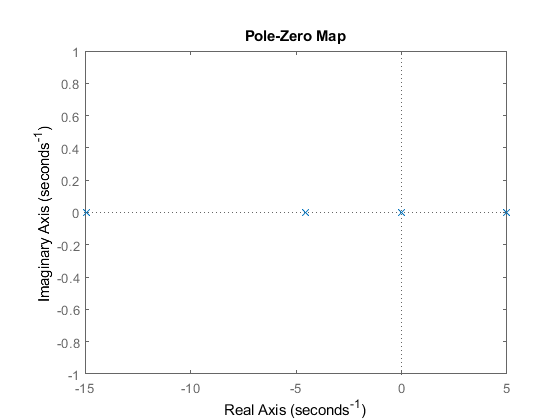

pzmap(G)

%Question4
eigenvalue_A=eig(A)

eigenvalue_A =          0
  -14.9300
   -4.5417
    4.9818


%Question5
Co=ctrb(A,B)

Co = 	1.0e+04 *

         0    0.0003   -0.0047    0.0703
    0.0003   -0.0047    0.0703   -1.0458
         0   -0.0010    0.0140   -0.2317
   -0.0010    0.0140   -0.2317    3.4396


rank_Co=rank(Co)

rank_Co = 4

%Question7
Mp=0.15;
ts=3;
zeta=((log(Mp)^2)/(pi^2+log(Mp)^2))^0.5

zeta = 0.5169

wn=3.9/(zeta*ts)

wn = 2.5148

Pd1=-zeta*wn+(wn*(1-zeta^2)^0.5)*1i

Pd1 = -1.3000 + 2.1528i

Pd2=-zeta*wn-(wn*(1-zeta^2)^0.5)*1i

Pd2 = -1.3000 - 2.1528i

%Question8
Pnd1= 15*Pd1

Pnd1 = -19.5000 + 32.2916i

Pnd2= 15*Pd2

Pnd2 = -19.5000 - 32.2916i

%Question9
p = [Pd1 Pd2 Pnd1 Pnd2];
K = 1.05*place(A,B,p)

K =  -124.5285  -59.2812 -210.9157  -22.8569
